% AE6511 Hw5 Problem 4(a) MATLAB code
% Tomoki Koike
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% solve for t_f
syms t_f 
V = 15;  % constant ship velocity
xf = -15;
yf = 35.5;
c3 = -20;

eqn = (V^2 - 40)*t_f^2 - (12*yf - 4*(xf - c3))*t_f - yf^2 - (xf - c3)^2 == 0;
tf_sol = solve(eqn, t_f);
tf = double(tf_sol(tf_sol > 0))  % tf solution

tf = 3.9524

% solve for theta_f
syms c_1 c_2 theta_f
assume(c_1, 'real');
assume(c_2, 'real');
assume(theta_f, 'real');
eqn1 = -15 == (V* cos(theta_f) + 2)*tf - 20;
eqn2 = 35.5 == (V* sin(theta_f) - 6)*tf;

sol_cos = solve(eqn1, theta_f);
sol_sin = solve(eqn2, theta_f);
thetaf = 1.6198;

% solve for c1 and c2
eqn3 = 1 + c_1*(V*cos(thetaf) + 2) + c_2*(V*sin(thetaf) - 6) == 0;
eqn4 = tan(thetaf) == c_2 / c_1;
[c1, c2] = solve([eqn3 eqn4], [c_1, c_2])

$$c1 = 0.0055$$

$$c2 = -0.1121$$

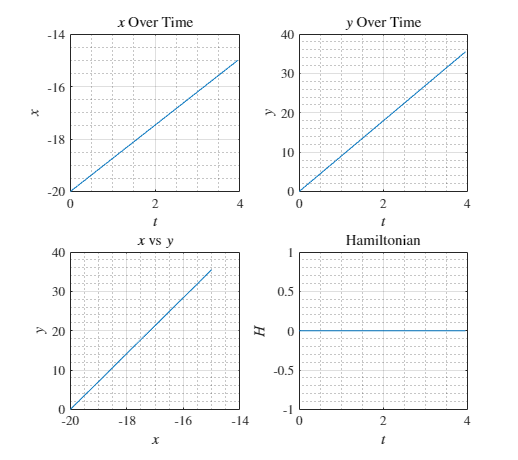

% Plotting 
tspan = linspace(0, tf, 1000);
x_t = (V*cos(thetaf) + 2).*tspan - 20;
y_t = (V*sin(thetaf) - 6).*tspan;
theta = thetaf * ones(size(tspan));
H = 1 + c1 * (V*cos(theta) + 2) + c2 * (V*sin(theta) - 6);

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x vs t
    subplot(2,2,1)
    plot(tspan, x_t)
    title('$x$ Over Time')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on;
    % y vs t
    subplot(2,2,2)
    plot(tspan, y_t)
    title('$y$ Over Time')
    xlabel('$t$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % x - y 
    subplot(2,2,3)
    plot(x_t, y_t)
    title('$x$ vs $y$')
    xlabel('$x$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig, 'p4a.png');

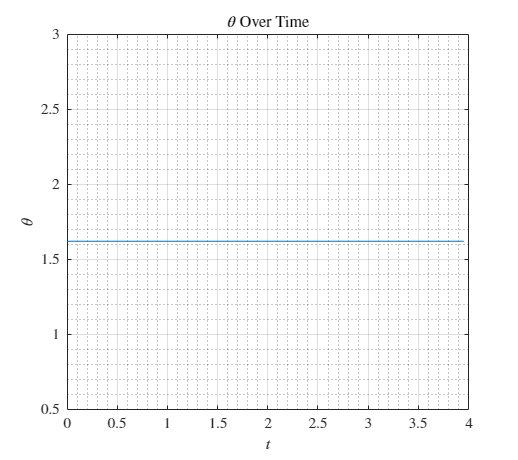

% Plot control 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, theta)
    title('$\theta$ Over Time')
    xlabel('$t$')
    ylabel('$\theta$')
    grid on; grid minor; box on;
saveas(fig, 'p4a_theta.png');